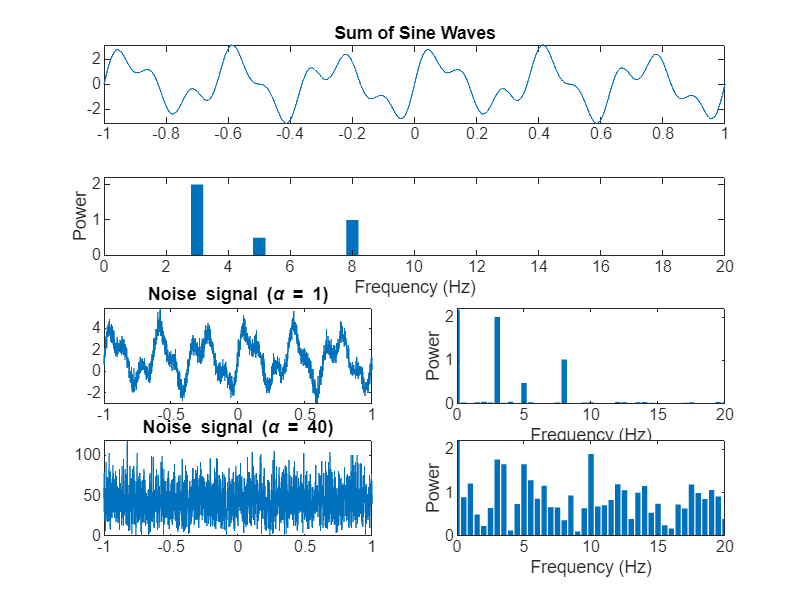

srate = 1000;
time = -1:1/srate:1;

s1 = 2*sin(2*pi*3*time);
s2 = 0.5*sin(2*pi*5*time);
s3 = sin(2*pi*8*time);

figure;

subplot(411)
plot(time, s1+s2+s3)
title("Sum of Sine Waves")

subplot(412)
fourier = fft(s1 + s2 + s3)/length(time);
hz = linspace(0,srate/2, floor(length(time)/2) + 1);
bar(hz, abs(fourier(1:length(hz)))*2)
set(gca, 'xlim', [0 20], 'ylim', [0 2.2])
xlabel("Frequency (Hz)")
ylabel("Power")

subplot(425)
alpha = 1;
noisy_signal = s1 + s2 + s3 + alpha * rand(1,length(time)) + alpha * rand(1,length(time)) .^ 2 + alpha * rand(1,length(time)) .^ 3;
plot(time, noisy_signal)
title("Noise signal (\alpha = 1)")

subplot(426)
fourier = fft(noisy_signal)/length(time);
hz = linspace(0,srate/2, floor(length(time)/2) + 1);
bar(hz, abs(fourier(1:length(hz)))*2)
set(gca, 'xlim', [0 20], 'ylim', [0 2.2])
xlabel("Frequency (Hz)")
ylabel("Power")

subplot(427)
alpha = 40;
noisy_signal = s1 + s2 + s3 + alpha * rand(1,length(time)) + alpha * rand(1,length(time)) .^ 2 + alpha * rand(1,length(time)) .^ 3;
plot(time, noisy_signal)
title("Noise signal (\alpha = 40)")

subplot(428)
fourier = fft(noisy_signal)/length(time);
hz = linspace(0,srate/2, floor(length(time)/2) + 1);
bar(hz, abs(fourier(1:length(hz)))*2)
set(gca, 'xlim', [0 20], 'ylim', [0 2.2])
xlabel("Frequency (Hz)")
ylabel("Power")